# Lab 6

## 6.2.2 Poles and zeros of z-transform

function showPolesAndZeros(num, den, name, showNorm, showPolesAndZeros)
    if nargin == 3 % showPolesAndZeros(num, den, name)
        showNorm = true;
        showPolesAndZeros = true;
    end
    
    if showPolesAndZeros
        disp(['Zeros of ', name])
        disp(roots(num))
        disp(['Poles of ', name])
        poles = roots(den);
        disp(poles)
    end
    
    zplane(num, den), title([name, ' Zero-Pole Plot'])
    
    if showNorm
        min_pole = min(abs(poles));
        max_pole = max(abs(poles));
        disp(['Max norm: ', num2str(max_pole)])
        disp(['Min norm: ', num2str(min_pole)])
    end
end

### (a)

Zeros of H1(z)
   1.8054 + 0.0000i
  -0.1269 + 1.5457i
  -0.1269 - 1.5457i
  -0.0528 + 0.6426i
  -0.0528 - 0.6426i
   0.5539 + 0.0000i

Poles of H1(z)


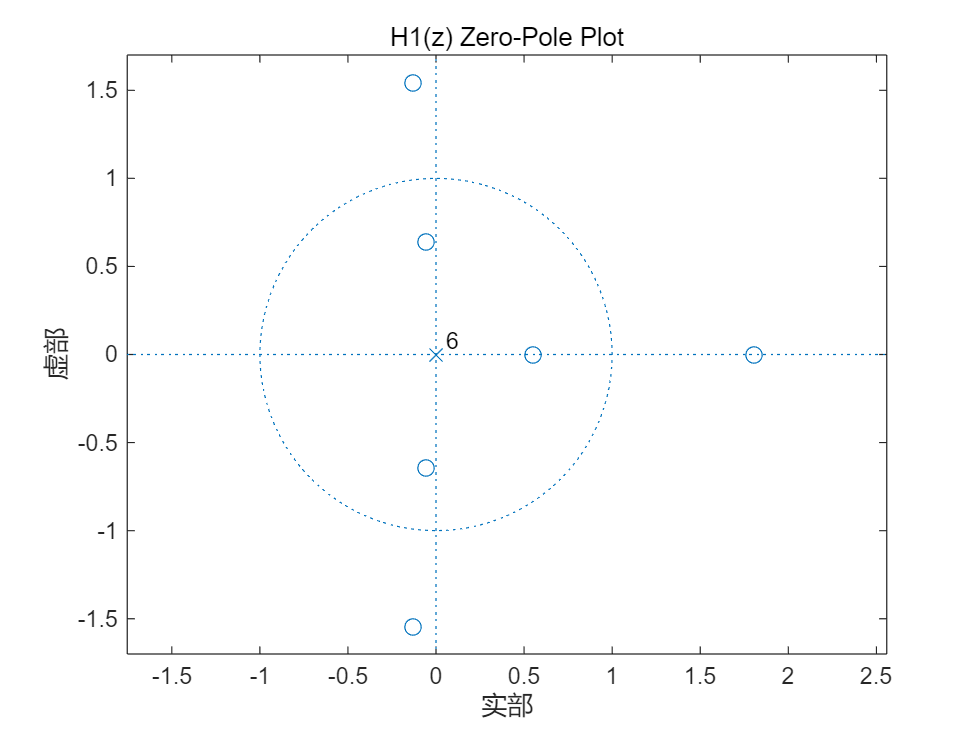

Max norm: 
Min norm: 


H1_num = [-1,2,-3,6,-3,2,-1];
H1_den = 1;
showPolesAndZeros(H1_num, H1_den, 'H1(z)')

`zplane()` generates a pole at the center which can be ignored. The  ROC is $|z|\ge 0$. It is a finite length sequence.

### (b)

Zeros of G1(z)
   0.6000 + 2.1541i
   0.6000 - 2.1541i
  -0.2000 + 0.7483i
  -0.2000 - 0.7483i

Poles of G1(z)
   0.9000 + 1.7861i
   0.9000 - 1.7861i
  -0.6000 + 0.0000i
   0.5000 + 0.0000i



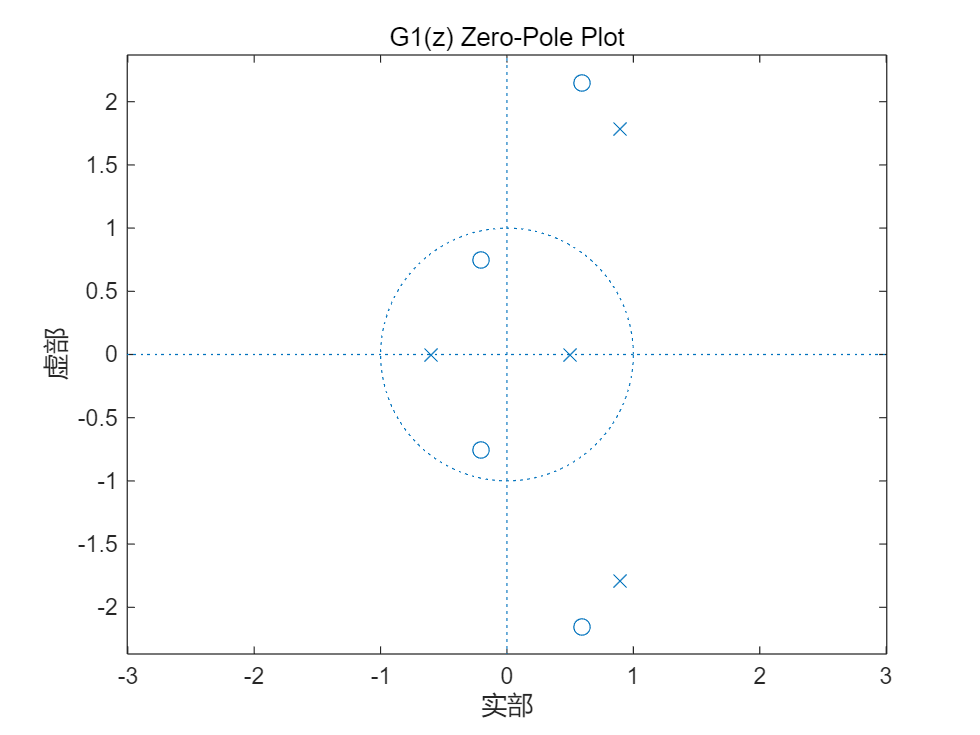

Max norm: 2
Min norm: 0.5


G1_num = [3, -2.4, 15.36, 3.84, 9];
G1_den = [5, -8.5, 17.6, 4.7, -6];
showPolesAndZeros(G1_num, G1_den, 'G1(z)')

Some poles are inside the unit circle, while some are outside of the unit circle.

$|z|<0\ldotp 5$: Left-sided

$0\ldotp 5<|z|<2$: Two-sided

$|z|>2$: Right-sided

Zeros of G2(z)
   0.3296 + 1.7980i
   0.3296 - 1.7980i
  -0.3796 + 0.4637i
  -0.3796 - 0.4637i

Poles of G2(z)
   0.8272 + 1.2744i
   0.8272 - 1.2744i
  -0.9272 + 1.1045i
  -0.9272 - 1.1045i



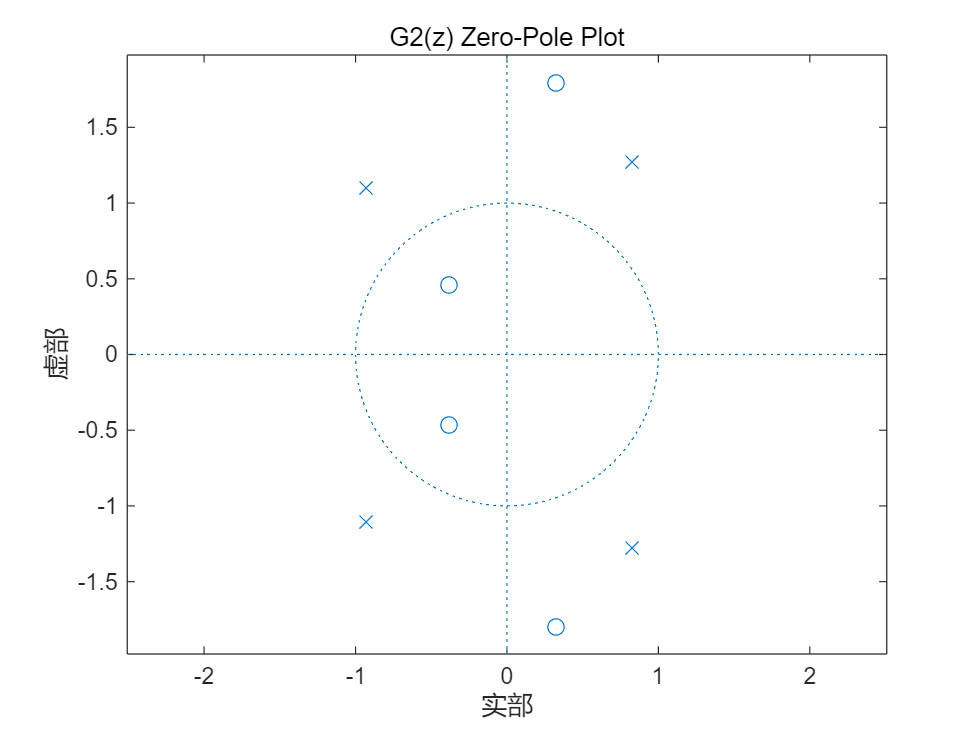

Max norm: 1.5193
Min norm: 1.4421


G2_num = [2, 0.2, 6.4, 4.6, 2.4];
G2_den = [5, 1, 6.6, 4.2, 24];
showPolesAndZeros(G2_num, G2_den, 'G2(z)')

$|z|<1\ldotp 4421$: Left-sided

$1\ldotp 4421<|z|<1\ldotp 5193$: Two-sided

$|z|>1\ldotp 5193$: Right-sided

### 6.2.3 z-transform and frequency response

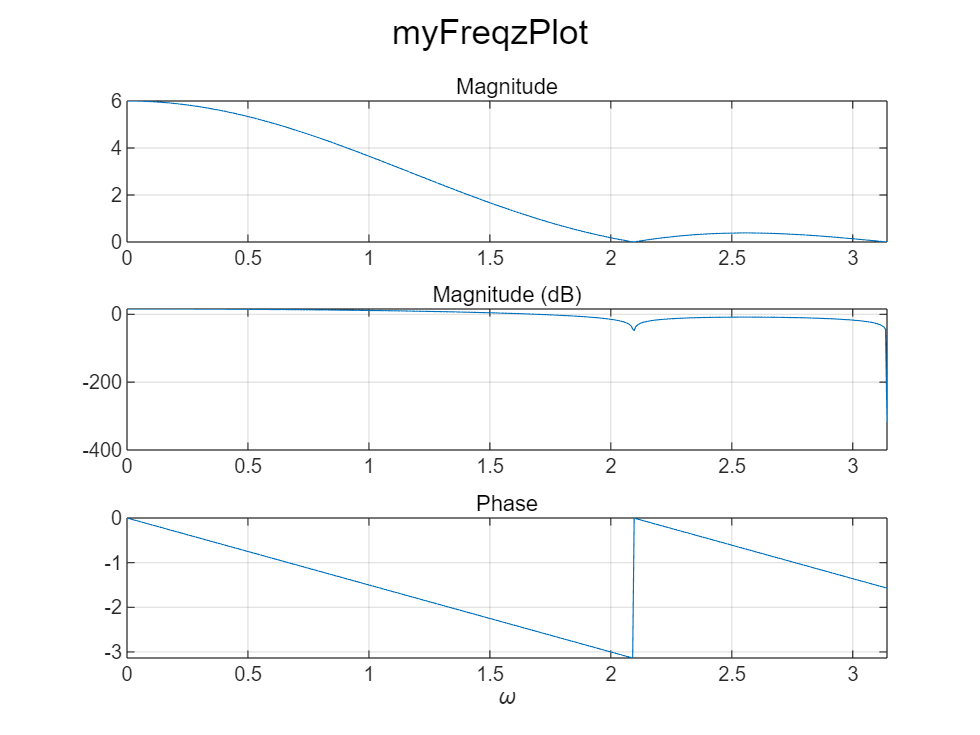

clear, figure
function [mag, phase]=FreRes(num, den)
    w = linspace(0, pi, 512);
    z = exp(1j*w);
    H = polyval(num, z) ./ polyval(den, z);
    mag = abs(H);
    phase = angle(H);
end

function myFreqzPlot(mag, phase, name)
    w = linspace(0, pi, 512);
    figure

    subplot(311)
    plot(w, mag), title('Magnitude'), grid on
    xlim([0,pi])
    
    subplot(312)
    plot(w, 20*log10(mag)), title('Magnitude (dB)'), grid on
    xlim([0,pi])
    
    subplot(313)
    plot(w, -phase), title('Phase'), grid on
    xlabel('\omega'), xlim([0,pi])

    sgtitle(name)
end
num = [1,2,2,1];
den = 1;
[mag, phase] = FreRes(num, den);

myFreqzPlot(mag, phase, 'myFreqzPlot')

Compare with `freqz()`: they are the same.

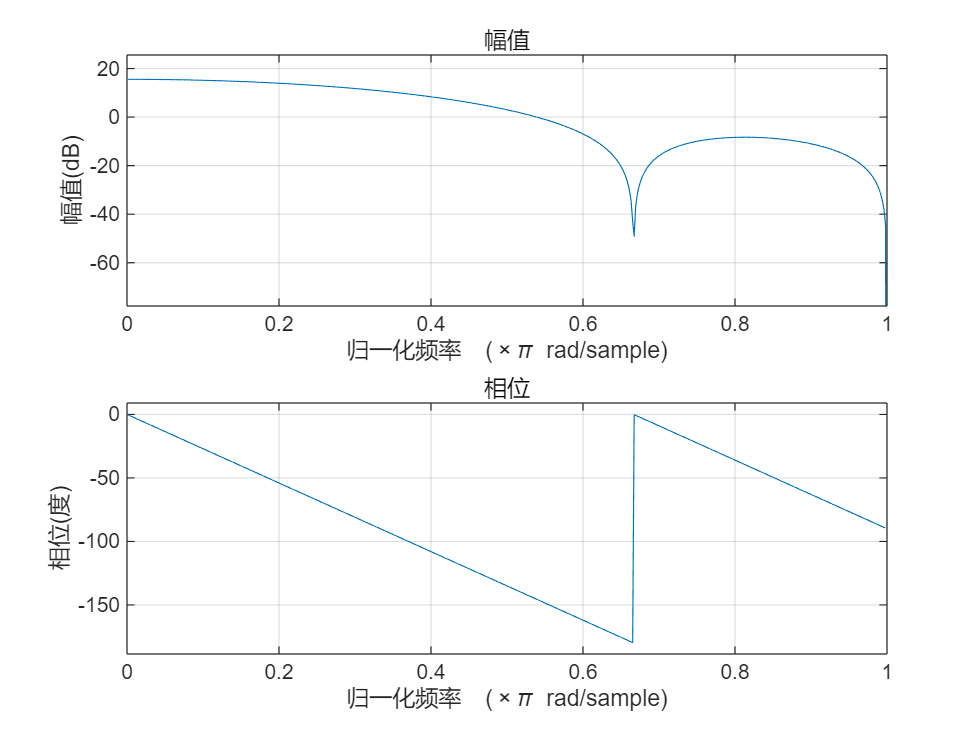

figure
w = linspace(0, pi, 512);
freqz(num, den, w)

### 6.2.4 Inverse z-transform

num = [3,-7.8];
den = conv([1,-0.7], [1, 1.6]);

[r, p, k] = residue(num, den)

r =     5.4783
   -2.4783


p =    -1.6000
    0.7000



k =

     []



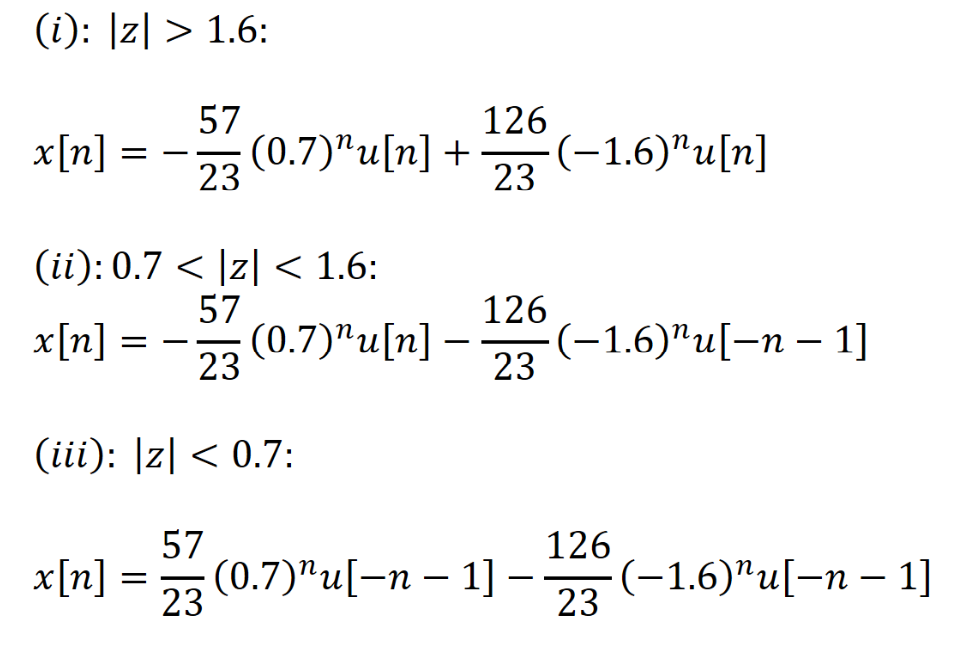

num = [3,1.8,1.28];
den = conv([1,-.5], [1,.4]);

[r,p,k]= residue(fliplr(num),fliplr(den))

r =     7.2222
  -13.0222


p =    -2.5000
    2.0000


k = -6.4000

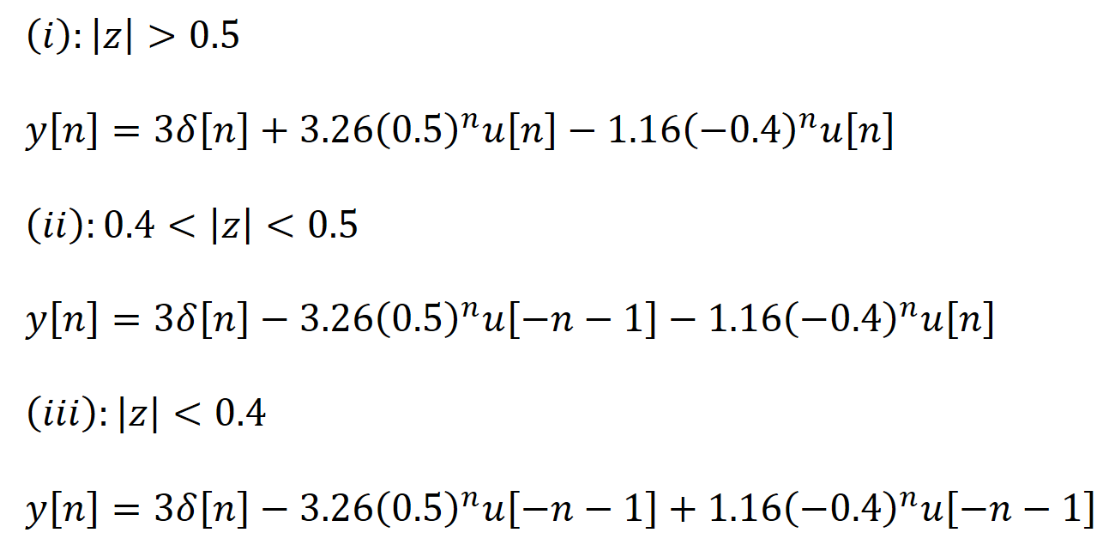

### 6.2.5 Stability Conditions

clear, figure

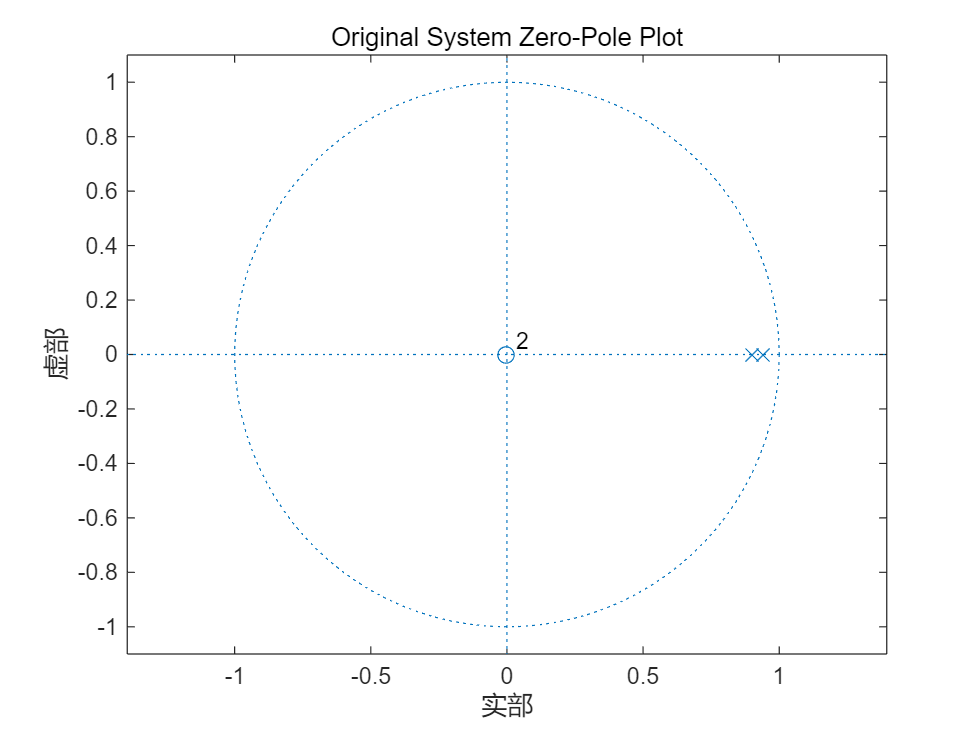

num = 1;
den = [1, -1.845, 0.850586];
showPolesAndZeros(num, den, 'Original System', false, false)

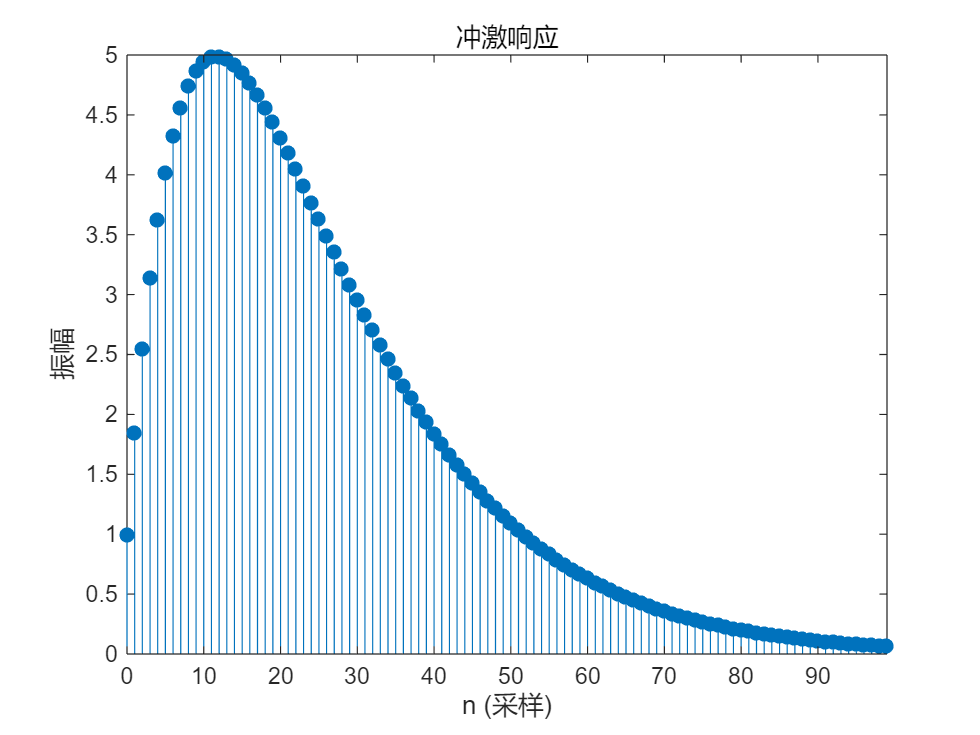

impz(num, den, 100)

Zeros of Quantified System
Poles of Quantified System
    1.0000
    0.8500



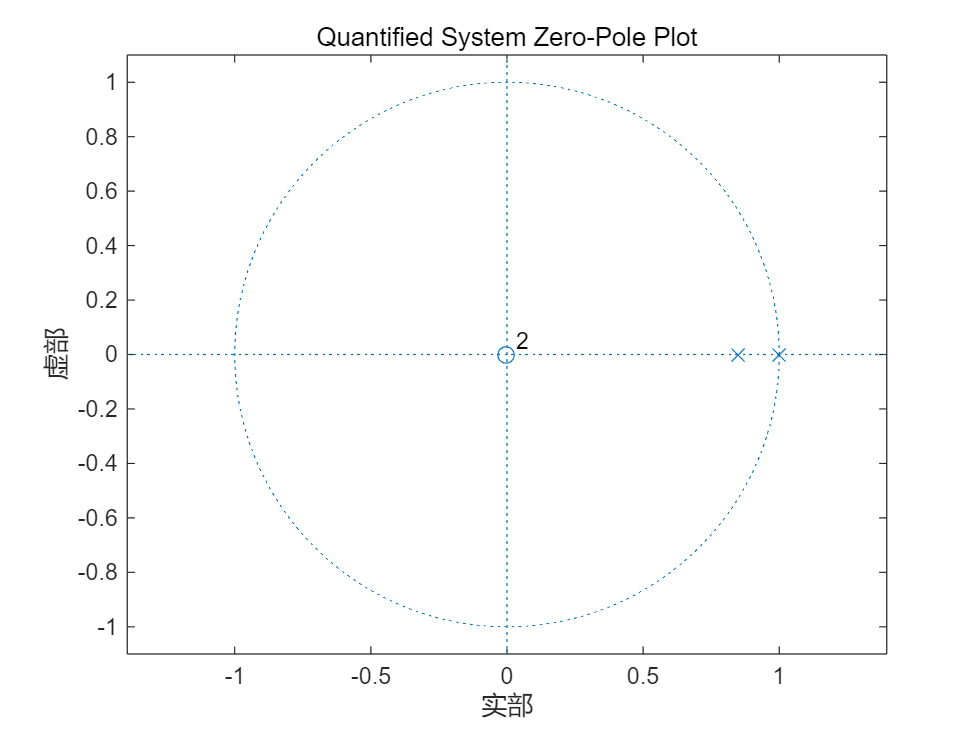

den = [1, -1.85, 0.85];
showPolesAndZeros(num, den, 'Quantified System', false, true)

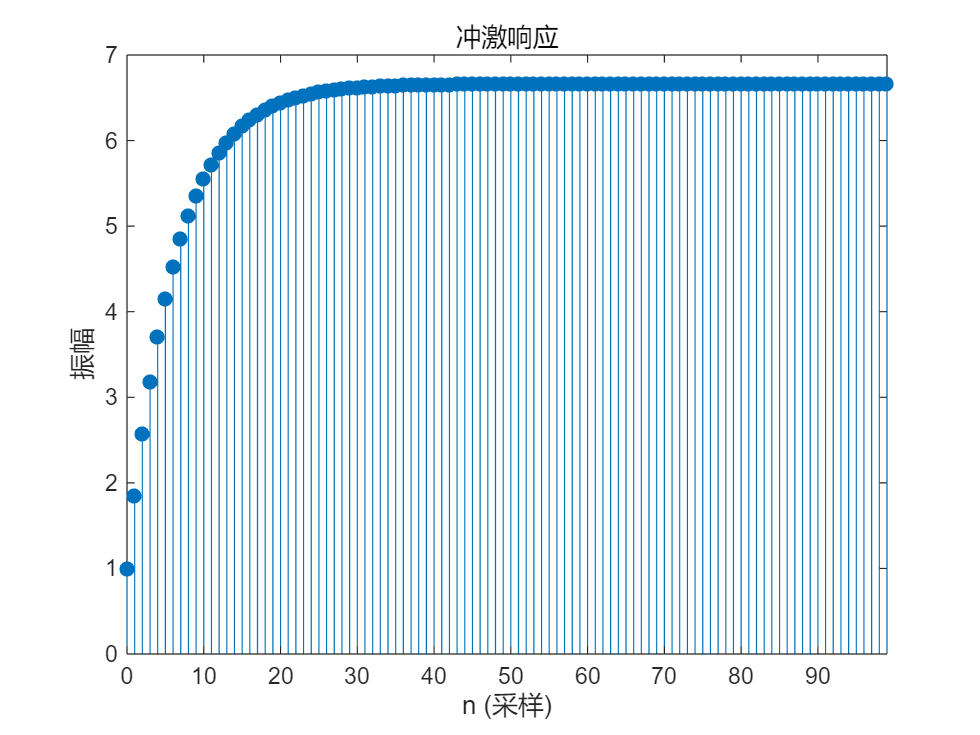

impz(num, den, 100)

The impulse response of the original system is absolute summable, and the poles all lies within the unit circle. Hence, the system is stable.

The impulse response of the quantified system is not summable, and a pole is not inside of the unit circle. The system is unstable.

## 6.3 Linear Phase FIR Filters

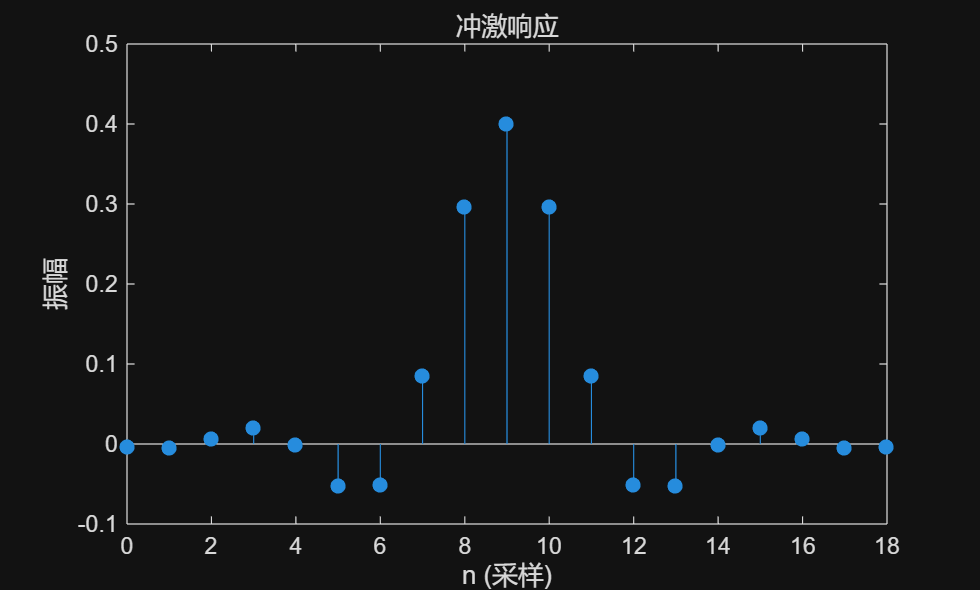

clear, figure
h = [-0.0035, -0.0039, 0.0072, 0.0201, -0.0000, -0.0517, -0.0506, 0.0855, 0.2965, 0.4008, 0.2965, 0.0855, -0.0506, -0.0517, -0.0000, 0.0201, 0.0072, -0.0039, -0.0035];
den = 1;
impz(h, den, 19)

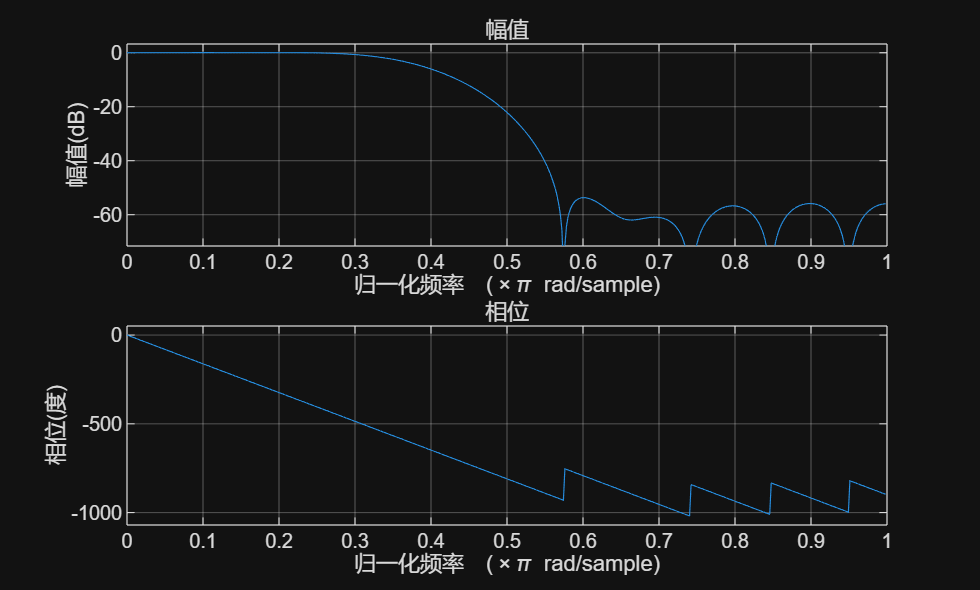

freqz(h, den)

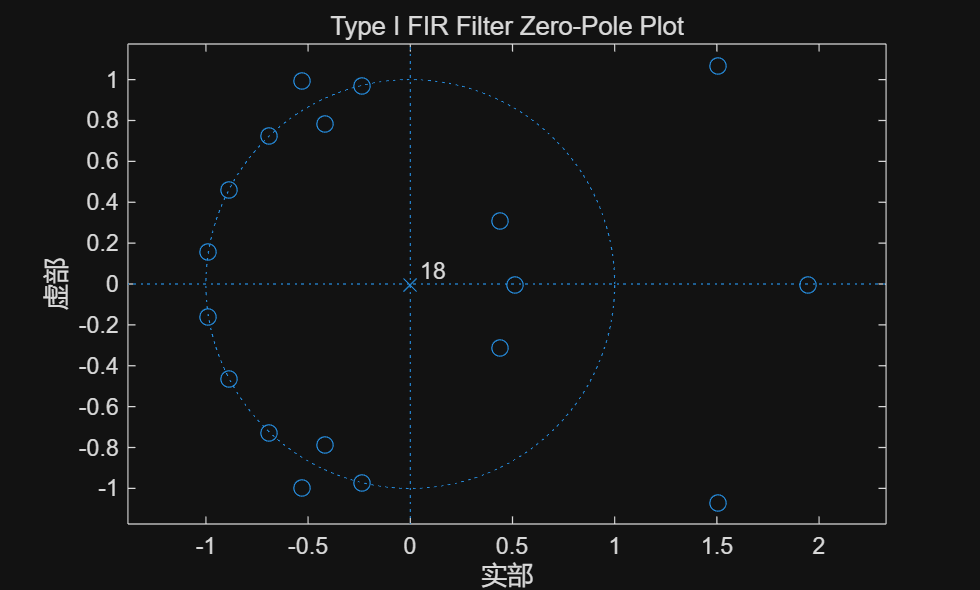

showPolesAndZeros(h, den, 'Type I FIR Filter', false, false)

The magnitude is symmetric about n=9. The zero-pole plot is symmetric about the real axis.

For Type III filters, their frequency response is pure imaginary and hence cannot be a LPF.

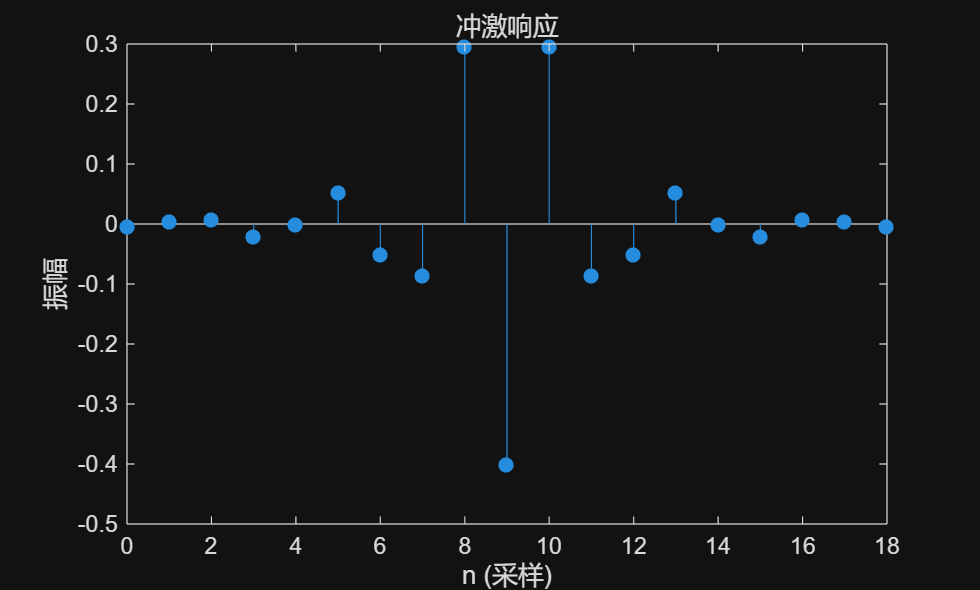

h1 = h;
h1(2:2:end) = -h(2:2:end);

impz(h1, den, 19)

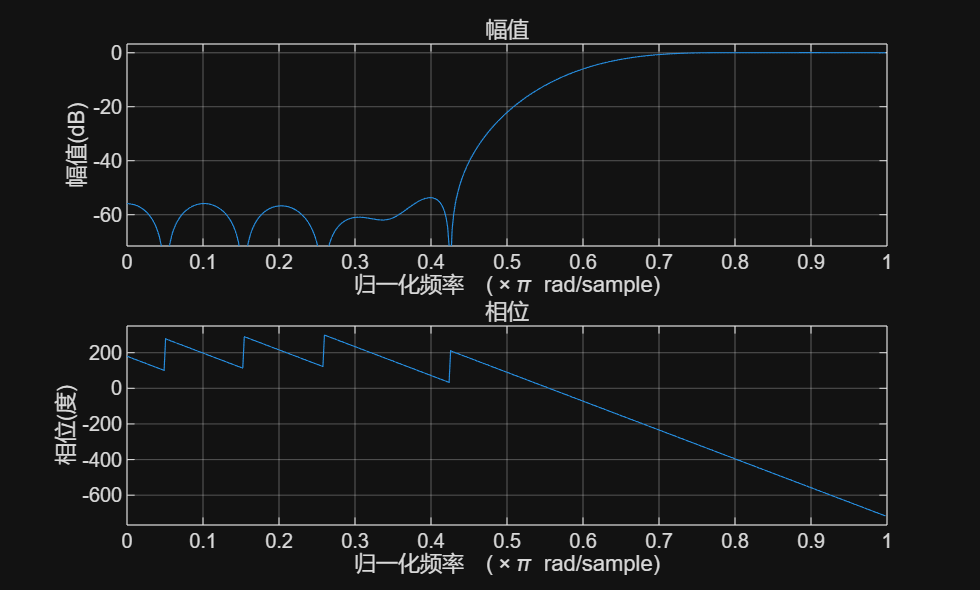

freqz(h1, den)

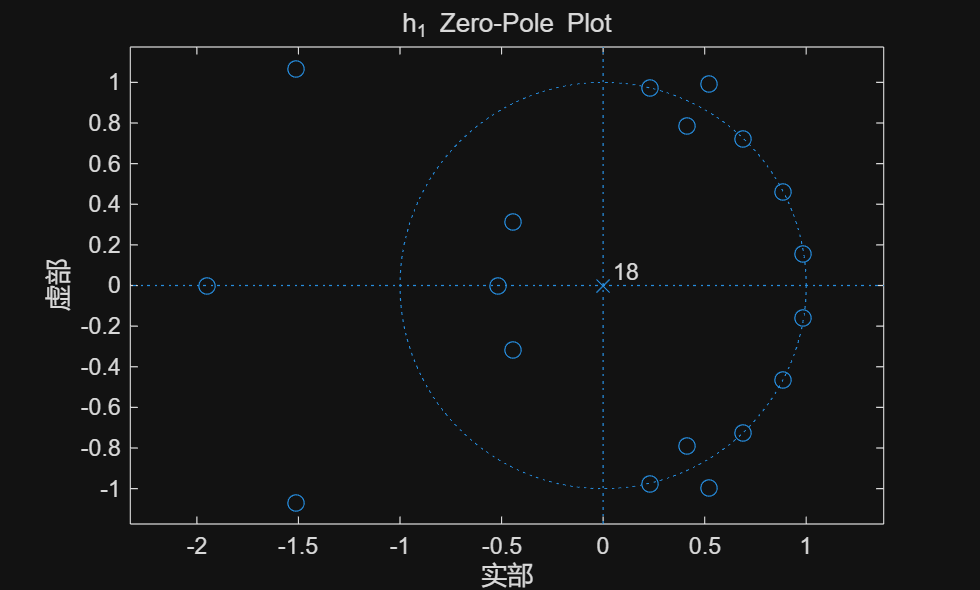

showPolesAndZeros(h1, den, 'h_1', false, false)

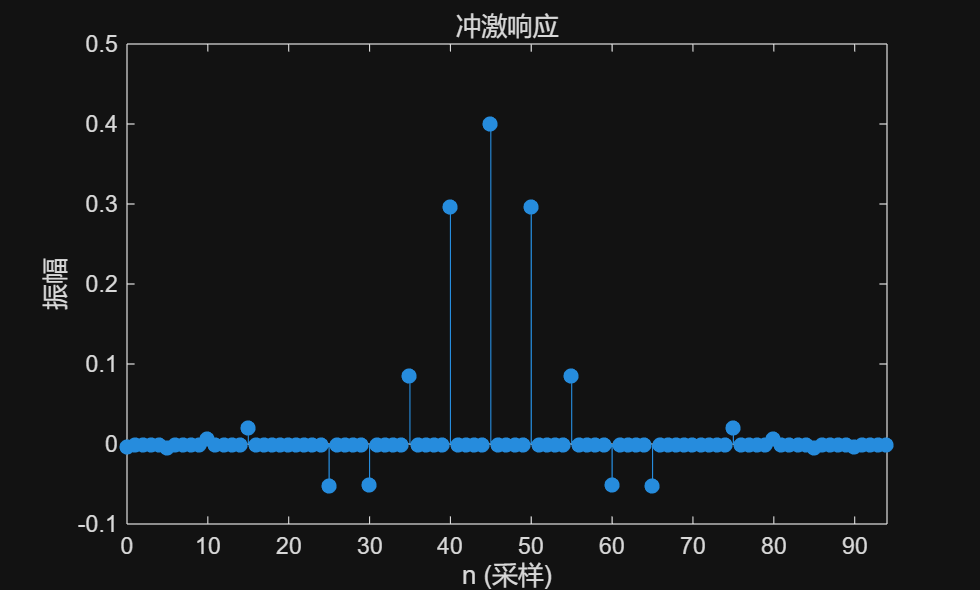

h2 = zeros(1, 5*length(h));
h2(1:5:end) = h;

impz(h2, den, 19*5)

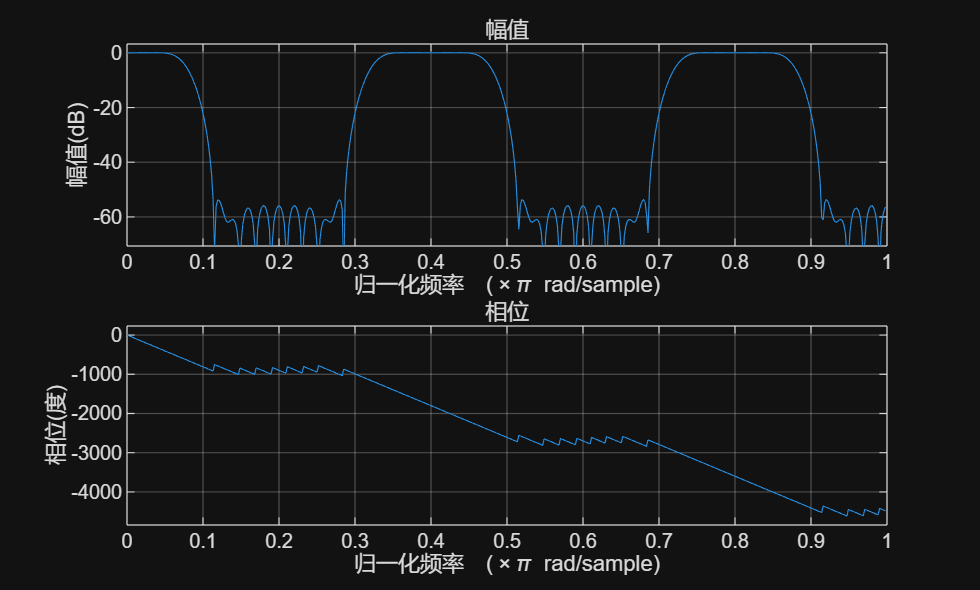

freqz(h2, den)

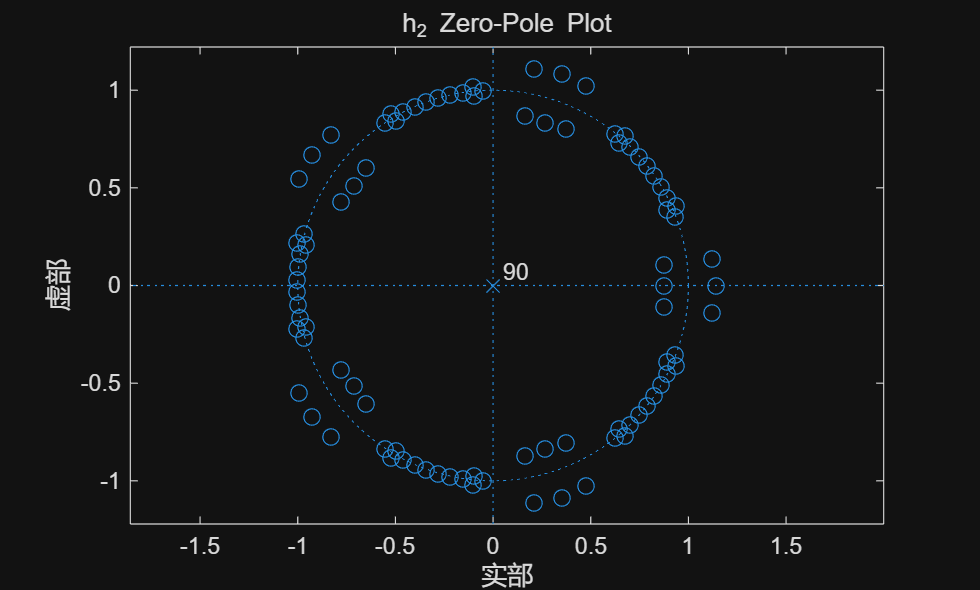

showPolesAndZeros(h2, den, 'h_2', false, false)

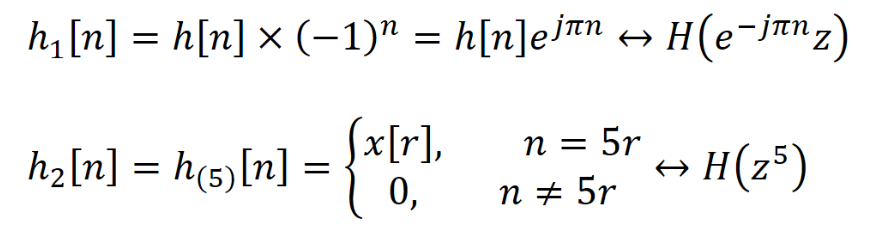

h1: The magnitude is reverted about pi/2. The phase shifted -pi (from pi to 0). The zero-pole plot is mirrored against the imaginary axis.

h2: The magnitude is compressed regarding the frequency axis and shrunk to 1/5 of its original width.

### 6.3.2 Design of Simple FIR Filters

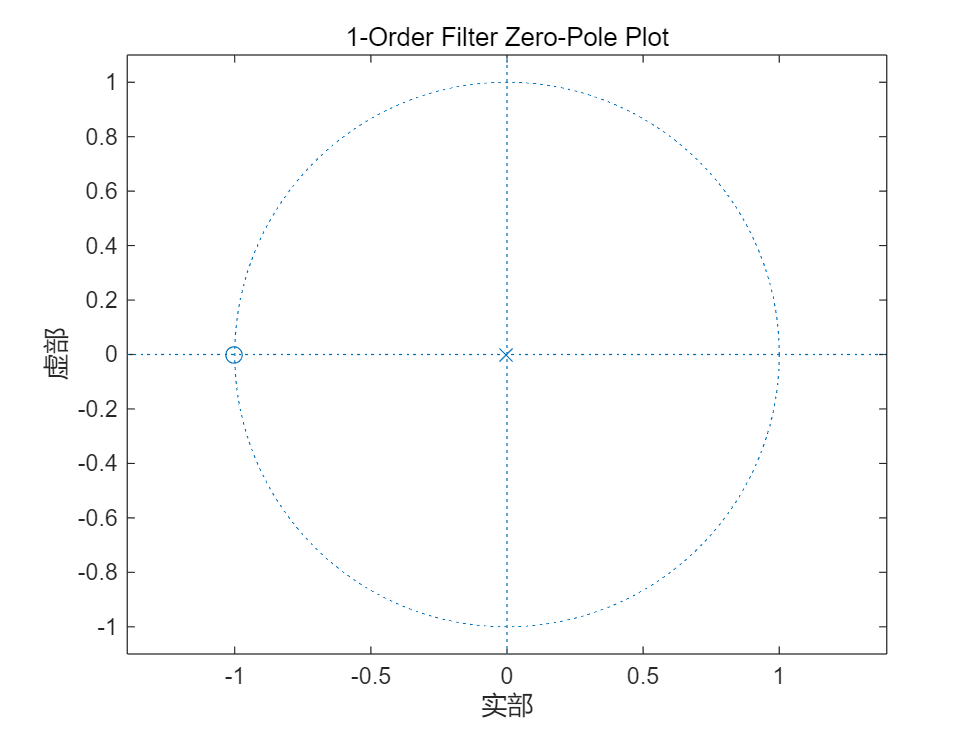

clear, figure

num = [1/2, 1/2];
den = 1;

showPolesAndZeros(num, den, '1-Order Filter', false, false)

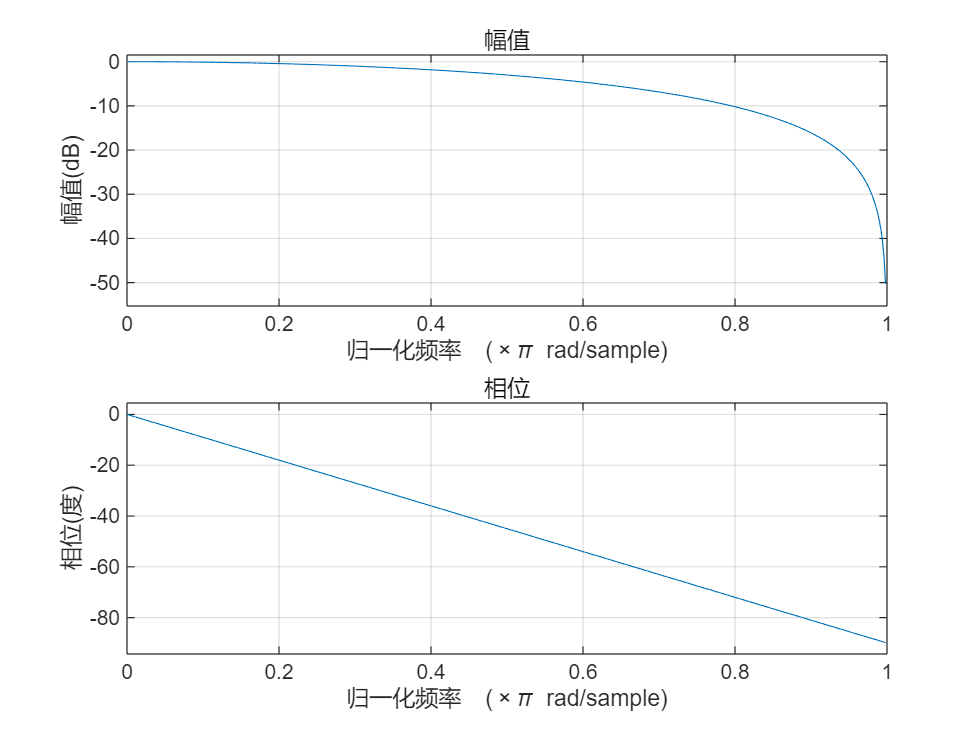

freqz(num,den)


function showActual3dBFrequency(num, den)
    [h, w] = freqz(num, den);
    [~, idx] = min(abs(abs(h) - 1/sqrt(2)));

    disp('Cutoff Frequency:')
    disp([num2str(w(idx)/pi), ' pi'])
end

(1)

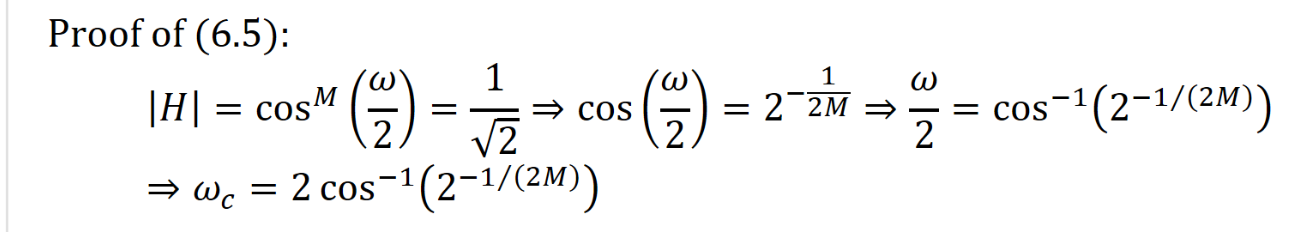

H_mag = @(M) cos(0.15*pi)^M - 1/sqrt(2);
M = fzero(H_mag, 1)

M = 3.0031

Cascade of 3 stages of (6.4) is needed.

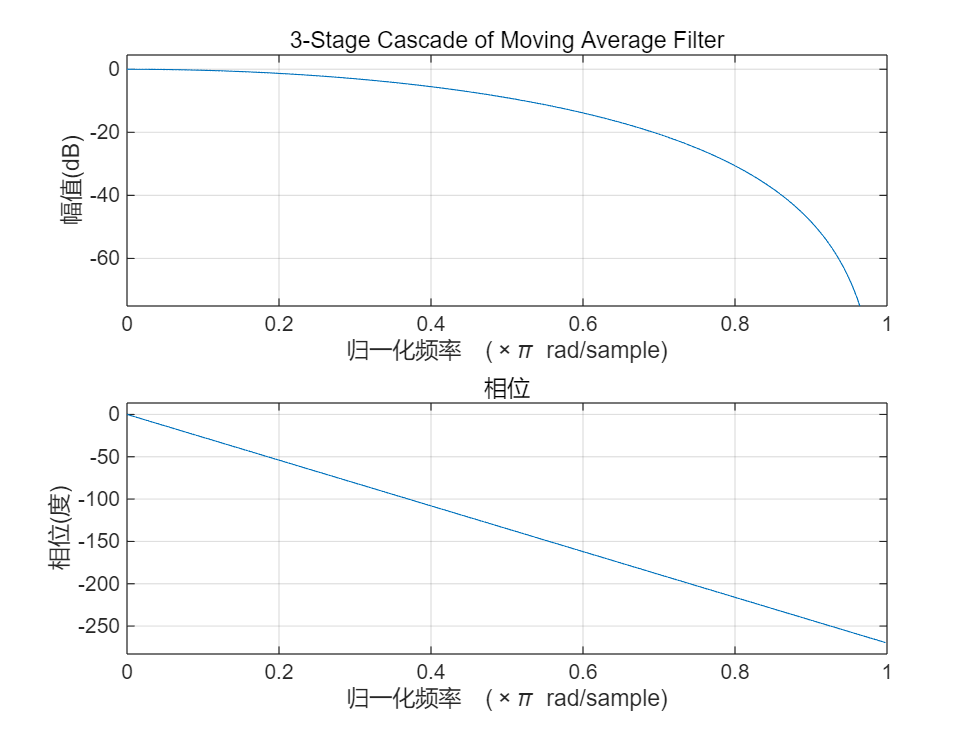

num1 = conv(num, conv(num, num));
freqz(num1, den); title('3-Stage Cascade of Moving Average Filter')

showActual3dBFrequency(num1, den)

Cutoff Frequency:
0.30078 pi


(2)

H_mag = @(M) 1/M*sin(M*.3*pi/2)/sin(.3*pi/2)-1/sqrt(2);
M = fzero(H_mag, 1)

M = 3.0955

3-order moving average filter is needed.

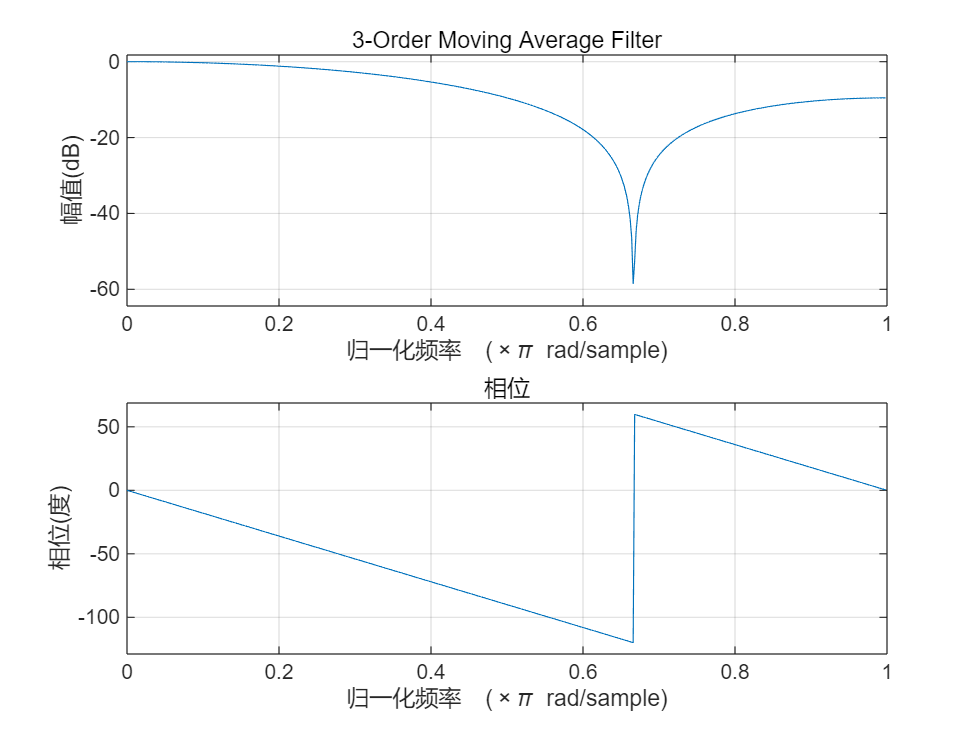

num2 = [1/3, 1/3, 1/3];
freqz(num2, den); title('3-Order Moving Average Filter')

showActual3dBFrequency(num2, den)

Cutoff Frequency:
0.31055 pi


The filter with cascades has no bumping.

The higher the number of stages or orders, the more similar they are to the ideal LPF.

### 6.4 IIR Filters

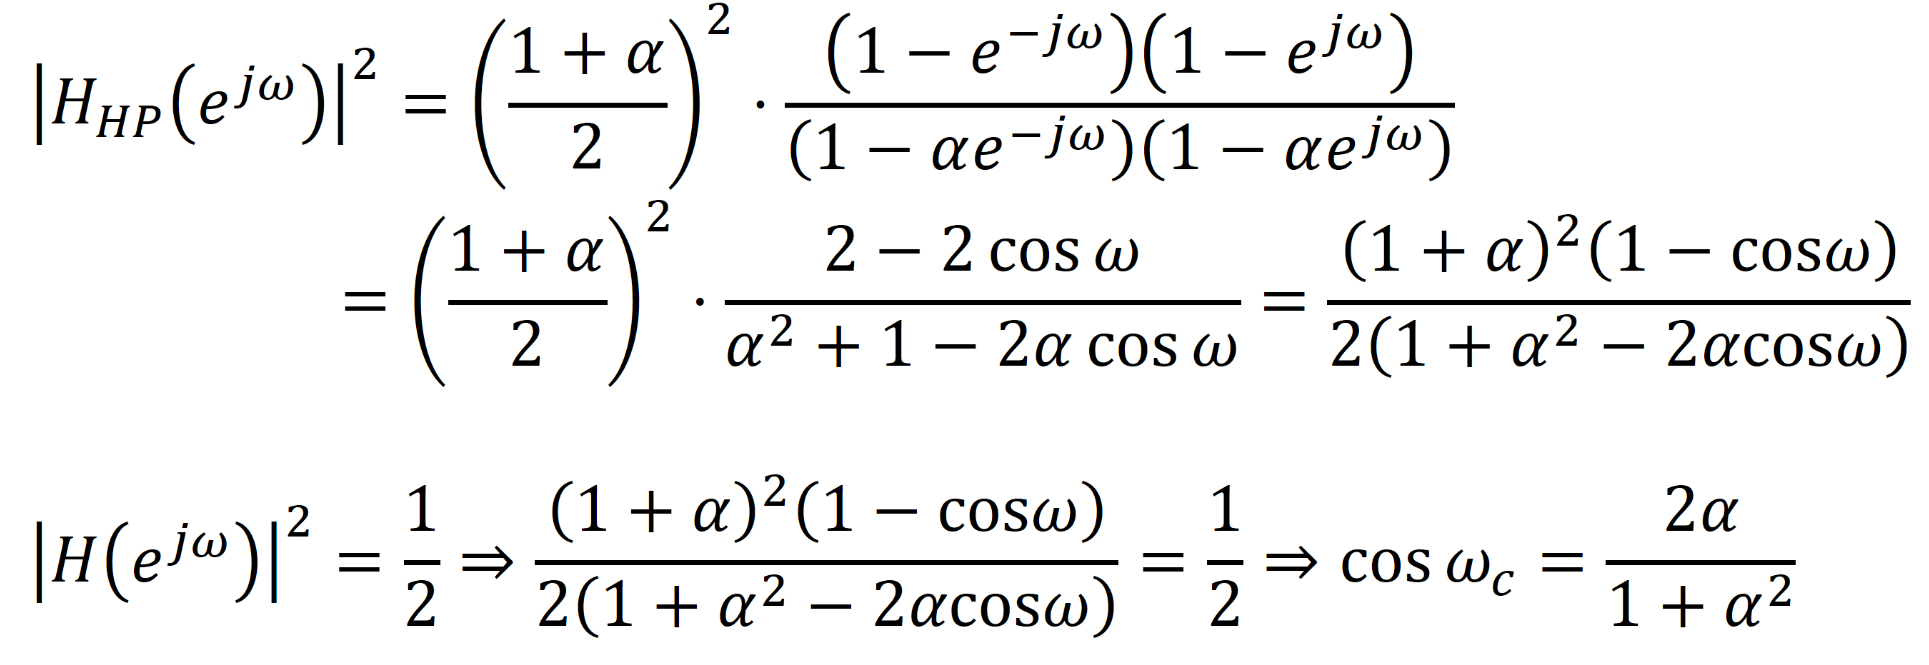

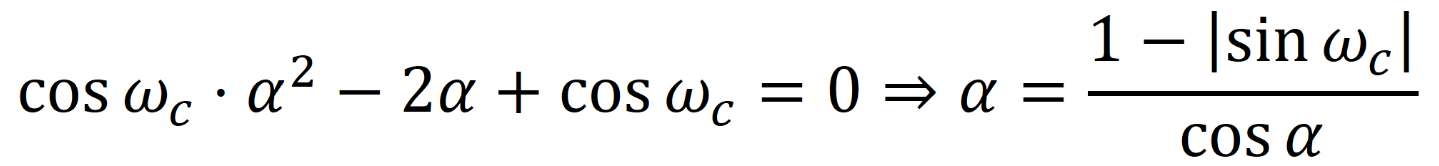

clear, figure

a = (1-sin(0.2*pi))/cos(0.2*pi)

a = 0.5095

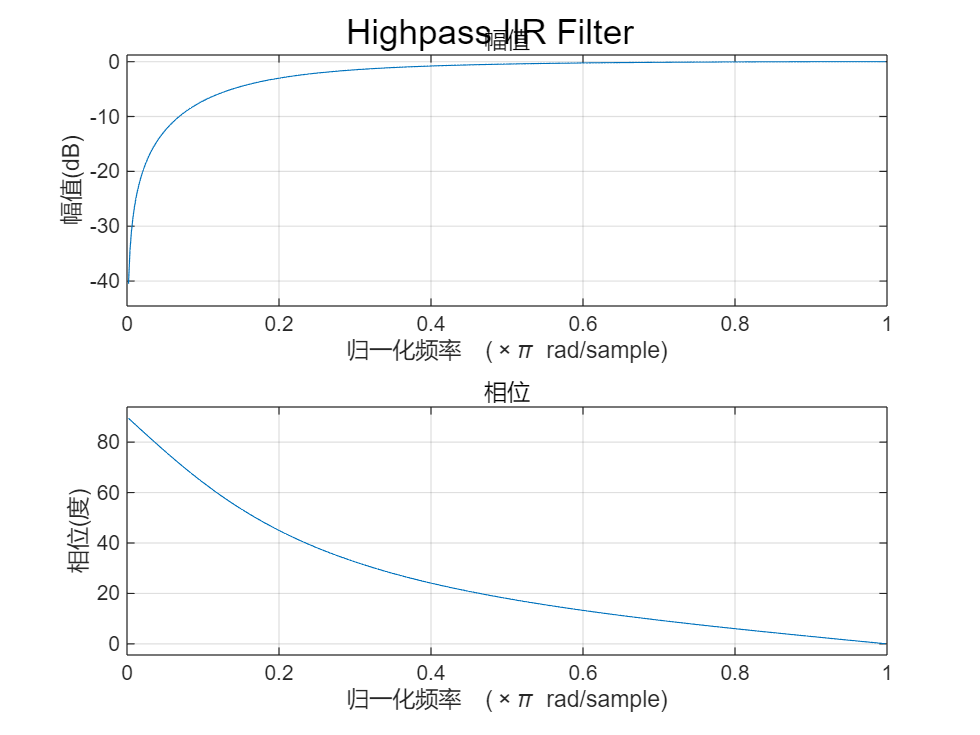


num = (1+a)/2.*[1, -1];

den = [1, -a];

freqz(num, den), sgtitle('Highpass IIR Filter')

showActual3dBFrequency(num, den)

Cutoff Frequency:
0.19922 pi


Our design matches our goal: it is HPF, and the cutoff frequency is almost equal to 0.2pi.